# Derivation of Quadrotor State Equations

To design the controller, the state-space equations first need to be derived. For the derivation, the following coordinate systems and motor numerations are assumed. Note that the z-axis is pointing downwards.

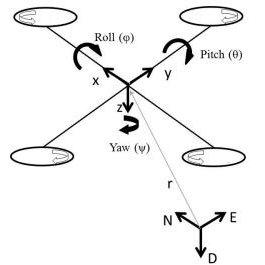

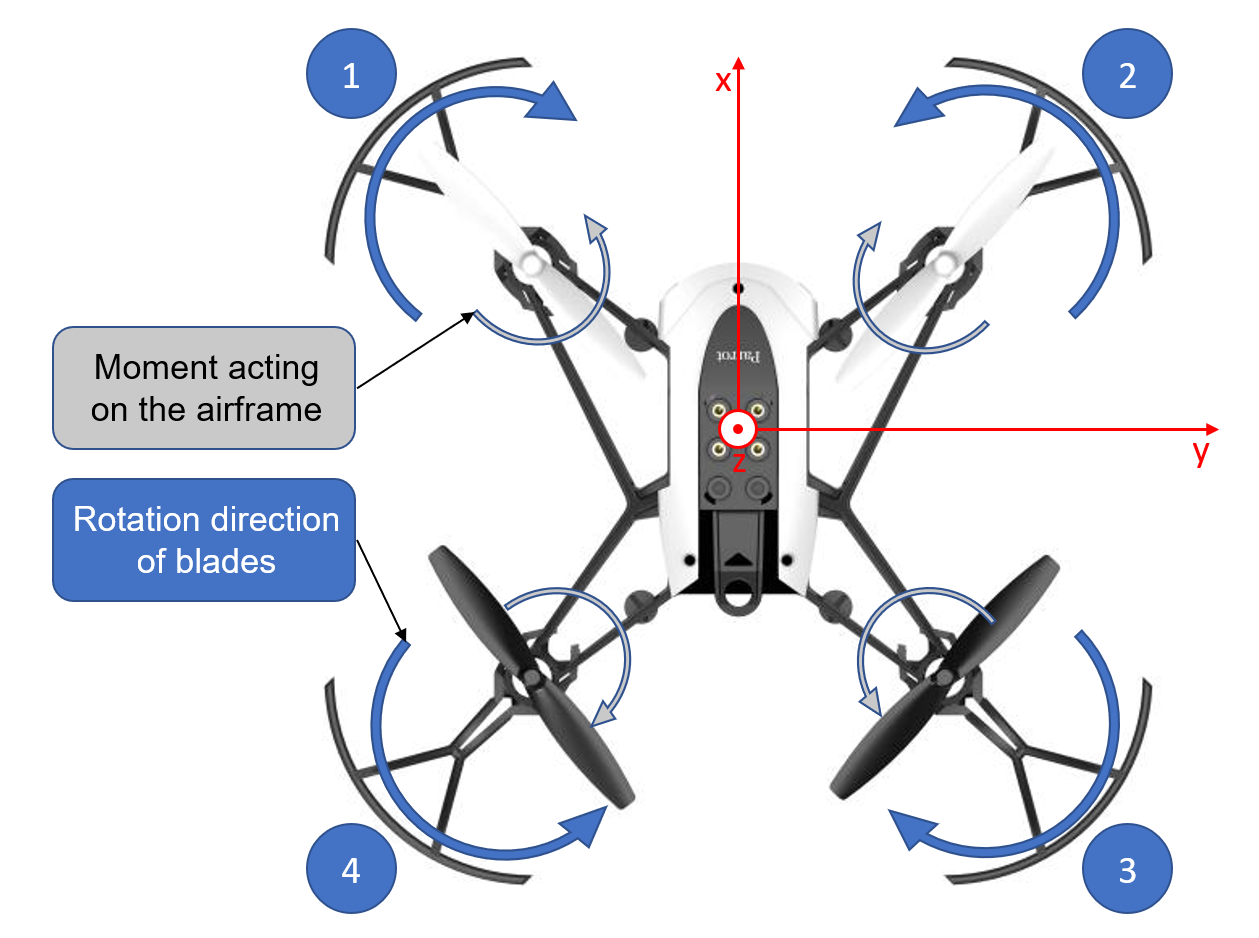

The Symbolic Toolbox is a perfect tool to derive the state equations and save them as MATLAB Functions. First, let's declare the symbolic variables for states, inputs (MVs) and parameters.

%Clear the variables from the workspace
clear;
%% Create symbolix variables for states, inputs, MVs and parameters
syms input_1 input_2 input_3 input_4 Ixx Iyy Izz k l m b g
syms x y z phi theta psi u v w p q r

where:

**States **

$x$: x position in global coordinates [m]

$y$: y position in global coordinates [m]

$z$: z position in global coordinates [m]

$\phi$ (phi): roll angle [rad]

$\theta$ (theta): pitch angle [rad]

$\psi$ (psi): yaw angle [rad]

$u$: x velocity in body frame of reference [m/s]

$v$: y velocity in body frame of refenence [m/s]

$w$: z velocity in body frame of reference [m/s]

$p$: angular velocity around x axis of body coordinate system [rad/s]

$q$: angular velocity around y axis of body coordinate system [rad/s]

$r$: angular velocity around z axis of body coordinate system [rad/s]

**Control Inputs**

$\omega^2_i/\omega_{max}^2$: squared velocity of rotor $i$ [rad^2/s^2] divided by the squared of the maximum rotor velocity [rad^2/s^2]

**Parameters**

$g$: gravitational acceleration [m/s^2]

$b$: rotor drag constant [kg*m^2]

$k$: rotor lift constant [kg*m]

$l$: moment arm between rotor and centre of mass [m]

$I_{ii}$ (Iii): diagonal elements of inertia matrix [kg*m^2]

For the Parrot Mambo, the parameters are:

## Set values for dynamics parameters

load UAV_NominalParameters % Make sure this is in your path
%IxxVal  %Units kg * m^2
%IyyVal  %Units kg * m^2
%IzzVal  %Units kg * m^2
%kVal  %Units N * s^2 = kg * m
%lVal  %Units m
%mVal  %Units kg
%bVal  %Units N * m * s^2= kg * m^2
%omegaMax2Val  %Units (rad / s)^2
gVal = 9.81; %Units kg * m / s^2

paramValues = [IxxVal IyyVal IzzVal kVal lVal mVal bVal gVal omegaMax2Val]

paramValues = 1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    6.9204


During the flight, the quadcopter's coordinated system will be rotating. Therefore, we need to relate it to the global coordinates using  a rotational matrix

%R-ZYX Euler
Rz = [cos(psi), -sin(psi), 0;
    sin(psi), cos(psi), 0;
    0, 0, 1]

$$Rz = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Ry = [cos(theta), 0, sin(theta);
    0, 1, 0;
    -sin(theta), 0, cos(theta)]

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Rx = [1, 0, 0;
    0, cos(phi), -sin(phi);
    0, sin(phi), cos(phi)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$


% Rotation matrix from body frame to inertial frame
R_Euler = Rz*Ry*Rx

$$R\_Euler = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

The thrust generated by the rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Recall that the input for propeller $i$ is $\omega^2_i/\omega_{max}^2\in[0,1]$. Therefore, the total thrust generated is 

% Thrust force
Fz = - k * (input_1 + input_2 + input_3 + input_4)*omegaMax2Val;

The produced thrust also generates moments around the x and y-axis:


$$L_i=\pm l \cdot F_{z_i} = \pm l \cdot k \cdot \omega^2_i$$



$$M_i=\pm l \cdot F_{z_i} = \pm l \cdot k \cdot \omega^2_i$$


where $L$ and $M$ are moments acting on the x and y-axis respectively and $l$ is the moment arm of the thrust. Due to symmetry of the drone the $l$ value is the same for both axis.

Additionaly, the drag created at the blades needs to be counteracted by motor torque:


$$N_i = \frac{\pm R \cdot Drag}{2} = \pm \frac{R}{4} \rho c_D V_{tip,i}^2 \cdot A_{ref}= \pm \frac{1}{4} \rho c_D R^3 \cdot A_{ref} \cdot \omega_i^2 = \pm b \cdot \omega^2_i$$


where $c_D$ is the drag coefficient related to the blade geometry. Similarly as with the thrust, all variables except $\omega^2$ are constant and substituted with a single parameter $b$. Therefore, the total acting moments are:

% Moments
L = k * l * (input_1 - input_2 - input_3 + input_4) * omegaMax2Val;
M = k * l * (input_1 + input_2 - input_3 - input_4) * omegaMax2Val;
N = b * (-input_1 + input_2 - input_3 + input_4) * omegaMax2Val;

Note the positive moments are defined by the right-hand rule. Having defined the acting forces and rotational matrix, we can start deriving equations of motion. Firstly, the rate of change of the global frame positions is simply the velocity vector in the global frame of reference:

% Position in global frame of reference
f(1:3) = [u; v; w];

The Euler angles rates are 

% Euler angles rates
f(4) = p + (q * sin(phi) + r * cos(phi)) * tan(theta);
f(5) = q * cos(phi) - r * sin(phi);
f(6) = (q * sin(phi) + r * cos(phi)) / cos(theta);

The linear acceleration of the system is obtained from Newton's Second Law, with the thrust vector rotated to the inertial frame:

% Acceleration in inertial frame
f(7:9) = R_Euler*[0;0;Fz]/m + [0;0;g];

Using the vector transport theorem, the angular acceleration of the system can be defined as 

% Rotational Acceleration
f(10) = (L + (Iyy - Izz) * q * r) / Ixx;
f(11) = (M + (Izz - Ixx) * p * r) / Iyy;
f(12) = (N + (Ixx - Iyy) * p * q) / Izz;

Use MATLAB [subs](https://www.mathworks.com/help/symbolic/subs.html) function to replace the parameters variables with their values and [simplify](https://www.mathworks.com/help/symbolic/simplify.html) the result:

% Replace parameters
f = subs(f, [Ixx Iyy Izz k l m b g omegaMax2Val], paramValues);      
f = simplify(f);                                        

Let us now group the states and normalised control inputs:

% Group symbolic variables
state = [x y z phi theta psi u v w p q r];
control = [input_1, input_2, input_3, input_4];

Having defined the state equations, obtain their Jacobians using [jacobian](https://www.mathworks.com/help/symbolic/sym.jacobian.html)

% Calculate linearization
A = jacobian(f,state);
B = jacobian(f,control);

Finally, save the obtained state dynamics function in $\dot{x}(t)=f(x(t),u(t))$and Jacobians as a Matlab Function using [matlabFunction](https://www.mathworks.com/help/symbolic/matlabfunction.html). Now they are ready to use in controller design.

%% Create appropriate files

% Create QuadrotorStateFcn.m
matlabFunction(transpose(f),'File','QuadrotorStateFcnBase',...
    'Vars',{transpose(state),transpose(control)});
% Create QuadrotorStateJacobianFcn.m 
matlabFunction(A, B,'File','QuadrotorStateJacobianFcnBase',...
    'Vars',{transpose(state),transpose(control)});

Having defined state equations, we can also find the motor speeds required to achieve equilibrium at given coordinates. 

To maintain stable position and orientation, all velocities need to be zero. This also means the pitch and yaw angle need to be zero as well.

Finally, look at the state equations and answer the following question: Does the position of the drone affect equilibrium? What would be the most convenient point to linearise at?

As an example, one can compute the equilibrium input when the states are all zero using MATLAB functions [subs](https://www.mathworks.com/help/symbolic/subs.html) and [solve](https://www.mathworks.com/help/symbolic/solve.html):

f_StatesZero = subs(f, state, zeros(1,12));                       
[input_Eq1, input_Eq2, input_Eq3, input_Eq4] = solve(f_StatesZero == 0, control);     
input_Eq = double([input_Eq1 input_Eq2 input_Eq3 input_Eq4])               

input_Eq =     0.4730    0.4730    0.4730    0.4730


%Save the result in a mat file
save('Equilibrium inputs', 'input_Eq')